## Q2 - part a | ARX

clc; clear

%%

load HW5_question2

u1 = Z1.u;
y1 = Z1.y;

u2 = Z2.u;
y2 = Z2.y;

u3 = Z3.u;
y3 = Z3.y;

u1_val = u1(601:end);
y1_val = y1(601:end);

u2_val = u2(601:end);
y2_val = y2(601:end);

u3_val = u1(601:end);
y3_val = y1(601:end);

u1 = u1(1:600);
y1 = y1(1:600);

u2 = u2(1:600);
y2 = y2(1:600);

u3 = u3(1:600);
y3 = y3(1:600);

#### System Z1

%%

% System Z1 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System I Identification Begins:------------------------------\n")

>>> System I Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u1)*Ts-Ts;
t_val = 0:Ts:length(u1_val)*Ts-Ts;
N = length(y1);
N_val = length(y1_val);

%%

fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    U = arx_U_builder_3(u1, y1, na, nb, nk);
    theta_hat_1 = inv(U'*U)*U'*y1;
    y_hat_1 = form_tf_lsim_2(theta_hat_1, u1, t, na, Ts);

    [r2_arx, mse_arx] = rSQR(y1, y_hat_1);

    error = y1 - y_hat_1;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);

    covariance = variance*inv(U'*U);
    cov = trace(covariance)/p;
    covs = [covs; cov];
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_arx, mse_arx, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_arx];
    MSEs = [MSEs; mse_arx];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.093926 | MSE=75.816369 | var=76.069935 | s_hat=45489.821374 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.289808 | MSE=59.425779 | var=59.824610 | s_hat=35655.467584 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.347672 | MSE=54.583989 | var=55.135342 | s_hat=32750.393402 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.330092 | MSE=56.054978 | var=56.812477 | s_hat=33632.986514 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.346183 | MSE=54.708603 | var=55.635867 | s_hat=32825.161577 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.471854 | MSE=44.193019 | var=45.094918 | s_hat=26515.811643 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.646119 | MSE=29.611268 | var=30.318704 | s_hat=17766.760571 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.793634 | MSE=17.267848 | var=17.740940 | s_hat=10360.708996 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.871345 | MSE=10.765263 | var=11.098209 | s_hat=6459.157794 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.898923 | MSE=8.457678 | var=8.749322 | s_hat=5074.607048 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.910834 | MSE=7.461007 | var=7.744990 | s_hat=4476.604262 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.916108 | MSE=7.019748 | var=7.312237 | s_hat=4211.848651 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.918121 | MSE=6.851283 | var=7.161620 | s_hat=4110.769836 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.919352 | MSE=6.748275 | var=7.078610 | s_hat=4048.964847 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.919832 | MSE=6.708127 | var=7.061186 | s_hat=4024.876049 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.919612 | MSE=6.726553 | var=7.105514 | s_hat=4035.932040 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.919029 | MSE=6.775321 | var=7.182319 | s_hat=4065.192792 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.918681 | MSE=6.804422 | var=7.238747 | s_hat=4082.653469 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.918954 | MSE=6.781570 | var=7.240110 | s_hat=4068.941875 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.919085 | MSE=6.770623 | var=7.254239 | s_hat=4062.373629 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.920108 | MSE=6.685008 | var=7.188181 | s_hat=4011.004949 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.920455 | MSE=6.655975 | var=7.182707 | s_hat=3993.585184 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.921769 | MSE=6.546063 | var=7.089599 | s_hat=3927.637913 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.922224 | MSE=6.507920 | var=7.073826 | s_hat=3904.752033 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.922725 | MSE=6.466009 | var=7.053828 | s_hat=3879.605344 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.923046 | MSE=6.439214 | var=7.050234 | s_hat=3863.528475 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.923093 | MSE=6.435243 | var=7.071695 | s_hat=3861.145694 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.923623 | MSE=6.390936 | var=7.048826 | s_hat=3834.561587 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.924193 | MSE=6.343210 | var=7.022004 | s_hat=3805.926120 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.923959 | MSE=6.362812 | var=7.069791 | s_hat=3817.686976 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.923962 | MSE=6.362516 | var=7.095742 | s_hat=3817.509377 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.923815 | MSE=6.374858 | var=7.136035 | s_hat=3824.914791 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.923923 | MSE=6.365763 | var=7.152543 | s_hat=3819.458009 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.924527 | MSE=6.315225 | var=7.122434 | s_hat=3789.135118 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.924718 | MSE=6.299253 | var=7.131230 | s_hat=3779.551963 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.925586 | MSE=6.226656 | var=7.075745 | s_hat=3735.993427 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.925741 | MSE=6.213635 | var=7.087797 | s_hat=3728.181058 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.925689 | MSE=6.218064 | var=7.119921 | s_hat=3730.838654 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.925931 | MSE=6.197805 | var=7.123913 | s_hat=3718.682840 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.926073 | MSE=6.185893 | var=7.137569 | s_hat=3711.536096 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.925783 | MSE=6.210189 | var=7.193269 | s_hat=3726.113493 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.925773 | MSE=6.210969 | var=7.222057 | s_hat=3726.581411 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.926281 | MSE=6.168512 | var=7.200598 | s_hat=3701.107322 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.926282 | MSE=6.168421 | var=7.228618 | s_hat=3701.052397 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.926534 | MSE=6.147345 | var=7.232171 | s_hat=3688.406965 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.926574 | MSE=6.143965 | var=7.256651 | s_hat=3686.378907 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.926672 | MSE=6.135785 | var=7.275634 | s_hat=3681.470842 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.926693 | MSE=6.134042 | var=7.302431 | s_hat=3680.424983 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.927089 | MSE=6.100851 | var=7.291854 | s_hat=3660.510771 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.927059 | MSE=6.103419 | var=7.324103 | s_hat=3662.051305 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.927157 | MSE=6.095219 | var=7.343637 | s_hat=3657.131291 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.926952 | MSE=6.112340 | var=7.393960 | s_hat=3667.404266 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.926903 | MSE=6.116471 | var=7.428912 | s_hat=3669.882380 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.926999 | MSE=6.108414 | var=7.449286 | s_hat=3665.048627 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.927077 | MSE=6.101908 | var=7.471724 | s_hat=3661.144618 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.927382 | MSE=6.076376 | var=7.470954 | s_hat=3645.825632 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.927550 | MSE=6.062339 | var=7.484369 | s_hat=3637.403324 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.927543 | MSE=6.062880 | var=7.515967 | s_hat=3637.727986 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.927631 | MSE=6.055560 | var=7.538041 | s_hat=3633.335936 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.927621 | MSE=6.056369 | var=7.570462 | s_hat=3633.821577 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.927471 | MSE=6.068881 | var=7.617842 | s_hat=3641.328606 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.927753 | MSE=6.045284 | var=7.620106 | s_hat=3627.170277 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.927885 | MSE=6.034254 | var=7.638297 | s_hat=3620.552575 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.927886 | MSE=6.034166 | var=7.670549 | s_hat=3620.499355 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.927986 | MSE=6.025855 | var=7.692580 | s_hat=3615.512798 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.927979 | MSE=6.026407 | var=7.726163 | s_hat=3615.844321 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.928016 | MSE=6.023313 | var=7.755338 | s_hat=3613.987591 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.927981 | MSE=6.026217 | var=7.792522 | s_hat=3615.730249 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.928349 | MSE=5.995428 | var=7.786269 | s_hat=3597.256505 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.928340 | MSE=5.996215 | var=7.821150 | s_hat=3597.728811 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.928499 | MSE=5.982901 | var=7.837862 | s_hat=3589.740822 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.928543 | MSE=5.979236 | var=7.867415 | s_hat=3587.541359 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=0.928334 | MSE=5.996705 | var=7.925160 | s_hat=3598.022757 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.928342 | MSE=5.996054 | var=7.959364 | s_hat=3597.632695 | 


-------------------------------------------------------------


>>> Degree = 75 : R2=0.928442 | MSE=5.987691 | var=7.983588 | s_hat=3592.614751 | 


-------------------------------------------------------------


>>> Degree = 76 : R2=0.928910 | MSE=5.948473 | var=7.966705 | s_hat=3569.083757 | 


-------------------------------------------------------------


>>> Degree = 77 : R2=0.928845 | MSE=5.953912 | var=8.009747 | s_hat=3572.347154 | 


-------------------------------------------------------------


>>> Degree = 78 : R2=0.928888 | MSE=5.950320 | var=8.040973 | s_hat=3570.191908 | 


-------------------------------------------------------------


>>> Degree = 79 : R2=0.928701 | MSE=5.965982 | var=8.098618 | s_hat=3579.588973 | 


-------------------------------------------------------------


>>> Degree = 80 : R2=0.928807 | MSE=5.957125 | var=8.123352 | s_hat=3574.274857 | 


-------------------------------------------------------------


>>> Degree = 81 : R2=0.928918 | MSE=5.947836 | var=8.147720 | s_hat=3568.701400 | 


-------------------------------------------------------------


>>> Degree = 82 : R2=0.929712 | MSE=5.881378 | var=8.093640 | s_hat=3528.827051 | 


-------------------------------------------------------------


>>> Degree = 83 : R2=0.929554 | MSE=5.894578 | var=8.149187 | s_hat=3536.746943 | 


-------------------------------------------------------------


>>> Degree = 84 : R2=0.931689 | MSE=5.716006 | var=7.938897 | s_hat=3429.603511 | 


-------------------------------------------------------------


>>> Degree = 85 : R2=0.931693 | MSE=5.715647 | var=7.975321 | s_hat=3429.387954 | 


-------------------------------------------------------------


>>> Degree = 86 : R2=0.931635 | MSE=5.720502 | var=8.019395 | s_hat=3432.301273 | 


-------------------------------------------------------------


>>> Degree = 87 : R2=0.931742 | MSE=5.711497 | var=8.044362 | s_hat=3426.898097 | 


-------------------------------------------------------------


>>> Degree = 88 : R2=0.931743 | MSE=5.711436 | var=8.082221 | s_hat=3426.861513 | 


-------------------------------------------------------------


>>> Degree = 89 : R2=0.931848 | MSE=5.702645 | var=8.108027 | s_hat=3421.587251 | 


-------------------------------------------------------------


>>> Degree = 90 : R2=0.932011 | MSE=5.689025 | var=8.127179 | s_hat=3413.415068 | 


-------------------------------------------------------------


>>> Degree = 91 : R2=0.931955 | MSE=5.693676 | var=8.172741 | s_hat=3416.205757 | 


-------------------------------------------------------------


>>> Degree = 92 : R2=0.931974 | MSE=5.692110 | var=8.209774 | s_hat=3415.266140 | 


-------------------------------------------------------------


>>> Degree = 93 : R2=0.931838 | MSE=5.703529 | var=8.265984 | s_hat=3422.117360 | 


-------------------------------------------------------------


>>> Degree = 94 : R2=0.931850 | MSE=5.702479 | var=8.304582 | s_hat=3421.487665 | 


-------------------------------------------------------------


>>> Degree = 95 : R2=0.932442 | MSE=5.652928 | var=8.272577 | s_hat=3391.756572 | 


-------------------------------------------------------------


>>> Degree = 96 : R2=0.933055 | MSE=5.601707 | var=8.237805 | s_hat=3361.024405 | 


-------------------------------------------------------------


>>> Degree = 97 : R2=0.933086 | MSE=5.599090 | var=8.274517 | s_hat=3359.453769 | 


-------------------------------------------------------------


>>> Degree = 98 : R2=0.933285 | MSE=5.582403 | var=8.290697 | s_hat=3349.441735 | 


-------------------------------------------------------------


>>> Degree = 99 : R2=0.933291 | MSE=5.581959 | var=8.331281 | s_hat=3349.175149 | 


-------------------------------------------------------------


>>> Degree = 100 : R2=0.933489 | MSE=5.565335 | var=8.348002 | s_hat=3339.200954 | 


-------------------------------------------------------------



fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 100 


na = bestFitDegree;
nb = bestFitDegree;
p = na+nb;

BestFitU = arx_U_builder_3(u1, y1, na, nb, nk);
BestFitModel_1 = inv(BestFitU'*BestFitU)*BestFitU'*y1;
BestFit_y_hat_1 = form_tf_lsim_2(BestFitModel_1, u1_val, t_val, na, Ts);

G =
 
                                                                                                         
    0.94 z^-1 + 1.568 z^-2 + 2.597 z^-3 + 3.04 z^-4 + 2.671 z^-5 + 1.966 z^-6 + 0.966 z^-7 + 0.2992 z^-8 
                                                                                                         
            - 0.4131 z^-9 - 0.5001 z^-10 - 0.6905 z^-11 - 0.268 z^-12 + 0.2823 z^-13 + 1.149 z^-14       
                                                                                                         
            + 1.293 z^-15 + 1.618 z^-16 + 1.706 z^-17 + 1.452 z^-18 + 0.9768 z^-19 + 0.4067 z^-20        
                                                                                                         
            - 0.03759 z^-21 - 0.4725 z^-22 - 0.7541 z^-23 - 0.3856 z^-24 - 0.106 z^-25 + 0.3588 z^-26    
                                                                                                         
            + 0.8493 z^-27 + 1.123 z^-28


fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 29 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 29 


na = minVarIndex;
nb = minVarIndex;
p = na+nb;

VarU = arx_U_builder_3(u1, y1, na, nb, nk);
VarModel_1 = inv(VarU'*VarU)*VarU'*y1;
Var_y_hat_1 = form_tf_lsim_2(VarModel_1, u1_val, t_val, na, Ts);

G =
 
                                                                                                       
    0.8255 z^-1 + 1.592 z^-2 + 2.477 z^-3 + 2.828 z^-4 + 2.448 z^-5 + 1.764 z^-6 + 0.8116 z^-7         
                                                                                                       
            + 0.2123 z^-8 - 0.3953 z^-9 - 0.52 z^-10 - 0.647 z^-11 - 0.2579 z^-12 + 0.275 z^-13        
                                                                                                       
            + 0.9874 z^-14 + 0.9923 z^-15 + 1.12 z^-16 + 1.268 z^-17 + 0.9681 z^-18 + 0.5871 z^-19     
                                                                                                       
            + 0.1328 z^-20 + 0.111 z^-21 - 0.2979 z^-22 - 0.5182 z^-23 - 0.1875 z^-24 - 0.1129 z^-25   
                                                                                                       
                                         - 0.09271 z^-26 +


fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | CoVariance Method=================\n")

===============Degree Extraction | CoVariance Method=================



maxCovIndex = find(covs == min(covs));
fprintf(">>> Since the minimum CovMatrix trace occurs in iteration %d ;\n", maxCovIndex)

>>> Since the minimum CovMatrix trace occurs in iteration 11 ;


fprintf("    Degree = %d \n", maxCovIndex)

    Degree = 11 


na = maxCovIndex;
nb = maxCovIndex;
p = na+nb;

CovU_1 = arx_U_builder_3(u1,y1,na,nb,1);
CovModel_1 = inv(CovU_1'*CovU_1)*CovU_1'*y1;

Cov_y_hat_1 = form_tf_lsim_2(CovModel_1, u1_val, t_val, na, Ts);

G =
 
                                                                                                       
    0.7172 z^-1 + 1.499 z^-2 + 2.178 z^-3 + 2.183 z^-4 + 1.503 z^-5 + 0.5843 z^-6 - 0.2748 z^          
                                                                                                       
                                           -7 - 0.5856 z^-8 - 0.7757 z^-9 - 0.4399 z^-10 - 0.3997 z^-11
                                                                                                       
  -------------------------------------------------------------------------------------------------------
                                                                                                         
  1 - 0.2167 z^-1 - 0.1972 z^-2 - 0.1151 z^-3 - 0.1244 z^-4 + 0.04059 z^-5 + 0.08103 z^-6 + 0.08924 z^-7 
                                                                                                         
                                           - 0.013


fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 15 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 15 



na = minAICIndex;
nb = minAICIndex;
p = na+nb;

AICU_1 = arx_U_builder_3(u1, y1, na, nb, nk);
AICModel_1 = inv(AICU_1'*AICU_1)*AICU_1'*y1;
AIC_y_hat_1 = form_tf_lsim_2(AICModel_1, u1_val, t_val, na, Ts);

G =
 
                                                                                                     
  0.7302 z^-1 + 1.531 z^-2 + 2.424 z^-3 + 2.708 z^-4 + 2.254 z^-5 + 1.565 z^-6 + 0.6697 z^-7         
                                                                                                     
          + 0.1183 z^-8 - 0.4081 z^-9 - 0.5127 z^-10 - 0.6912 z^-11 - 0.4428 z^-12 - 0.1676 z^-13    
                                                                                                     
                                                                       + 0.229 z^-14 - 0.002193 z^-15
                                                                                                     
  ---------------------------------------------------------------------------------------------------
                                                                                                     
  1 - 0.1098 z^-1 - 0.1039 z^-2 - 0.02947 z^-3 - 0.06636 z^-4 + 0.04095 z^-5


fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.22 as


fprintf("    Degree = %d \n", winner)

    Degree = 14 



na = winner;
nb = winner;
p = na+nb;

FTestU_1 = arx_U_builder_3(u1, y1, na, nb, nk);
FTestModel_1 = inv(FTestU_1'*FTestU_1)*FTestU_1'*y1;
FTest_y_hat_1 = form_tf_lsim_2(FTestModel_1, u1_val, t_val, na, Ts);

G =
 
                                                                                                     
  0.7264 z^-1 + 1.522 z^-2 + 2.405 z^-3 + 2.671 z^-4 + 2.177 z^-5 + 1.428 z^-6 + 0.5016 z^-7         
                                                                                                     
          - 0.05858 z^-8 - 0.5852 z^-9 - 0.6322 z^-10 - 0.7477 z^-11 - 0.4356 z^-12 - 0.0874 z^-13   
                                                                                                     
                                                                                        + 0.312 z^-14
                                                                                                     
  ---------------------------------------------------------------------------------------------------
                                                                                                     
  1 - 0.1144 z^-1 - 0.1159 z^-2 - 0.04627 z^-3 - 0.07898 z^-4 + 0.02844 z^-5


fprintf("=================================================================\n")


%%

[BestFit_r2, BestFit_mse] = rSQR(y1_val, BestFit_y_hat_1);
[Var_r2, Var_mse] = rSQR(y1_val, Var_y_hat_1);
[AIC_r2, AIC_mse] = rSQR(y1_val, AIC_y_hat_1);
[Cov_r2, Cov_mse] = rSQR(y1_val, Cov_y_hat_1);
[FTest_r2, FTest_mse] = rSQR(y1_val, FTest_y_hat_1);


fprintf("===========================System III===========================\n")

===========================System III===========================


fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", BestFit_r2, BestFit_mse)

    R2 value : 0.6424   | MSE : 26.4444 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Var_r2, Var_mse)

    R2 value : 0.6718   | MSE : 24.2699 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Covariance Method:\n")

>>> Covariance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Cov_r2, Cov_mse)

    R2 value : 0.7094   | MSE : 21.4933 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", AIC_r2, AIC_mse)

    R2 value : 0.6904   | MSE : 22.8949 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", FTest_r2, FTest_mse)

    R2 value : 0.6946   | MSE : 22.5857 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

BestFitError_1 = y1_val - BestFit_y_hat_1;
VarError_1 = y1_val - Var_y_hat_1;
CovError_1 = y1_val - Cov_y_hat_1;
AICError_1 = y1_val - AIC_y_hat_1;
FTestError_1 = y1_val - FTest_y_hat_1;


for k=0:N_val-1
    BestFit_Ree_1(k+1,1) = AutoCorrelate(BestFitError_1, k);
    Var_Ree_1(k+1,1) = AutoCorrelate(VarError_1, k);
    Cov_Ree_1(k+1,1) = AutoCorrelate(CovError_1, k);
    AIC_Ree_1(k+1,1) = AutoCorrelate(AICError_1, k);
    FTest_Ree_1(k+1,1) = AutoCorrelate(FTestError_1, k);
end

for k=0:N_val-1
    BestFit_Rue_1(k+1,1) = CrossCorrelate(u1_val, BestFitError_1, k);
    Var_Rue_1(k+1,1) = CrossCorrelate(u1_val, VarError_1, k);
    Cov_Rue_1(k+1,1) = CrossCorrelate(u1_val, CovError_1, k);
    AIC_Rue_1(k+1,1) = CrossCorrelate(u1_val, AICError_1, k);
    FTest_Rue_1(k+1,1) = CrossCorrelate(u1_val, FTestError_1, k);
end


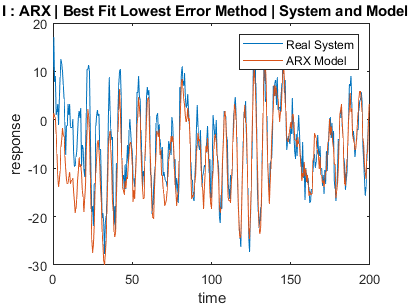


%%
figure()  % figure(1)
plot(t_val,y1_val,t_val,BestFit_y_hat_1)
legend('Real System','ARX Model')
title(" System I : ARX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

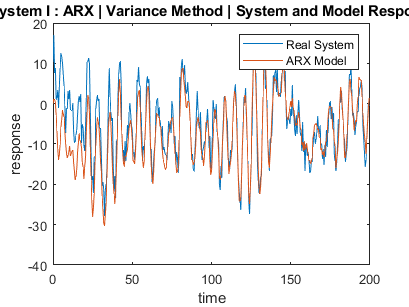


figure()  % figure(2)
plot(t_val,y1_val,t_val,Var_y_hat_1)
legend('Real System','ARX Model')
title(" System I : ARX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

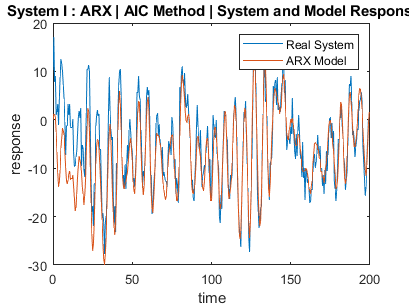


figure()  % figure(3)
plot(t_val,y1_val,t_val,AIC_y_hat_1)
legend('Real System','ARX Model')
title(" System I : ARX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

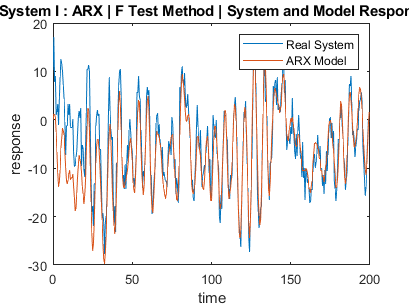


figure()  % figure(4)
plot(t_val,y1_val,t_val,FTest_y_hat_1)
legend('Real System','ARX Model')
title(" System I : ARX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

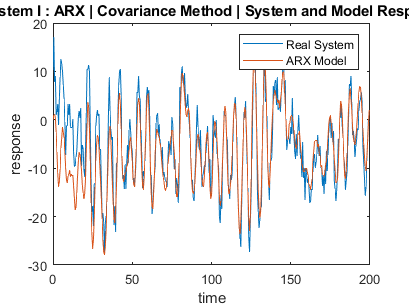


figure()  % figure(7)
plot(t_val,y1_val,t_val,Cov_y_hat_1)
legend('Real System','ARX Model')
title(" System I : ARX | Covariance Method | System and Model Response")
xlabel("time")
ylabel("response")

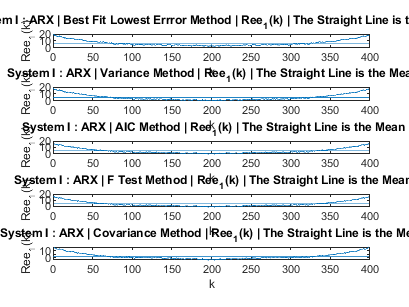


%%

figure()  % figure(5)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Ree_1(2:end), 1:N_val-1, mean(BestFit_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | Best Fit Lowest Errror Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Ree_1(2:end), 1:N_val-1, mean(Var_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | Variance Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Ree_1(2:end), 1:N_val-1, mean(AIC_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | AIC Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Ree_1(2:end), 1:N_val-1, mean(FTest_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | F Test Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,5)
plot(1:N_val-1,Cov_Ree_1(2:end), 1:N_val-1, mean(Cov_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | Covariance Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

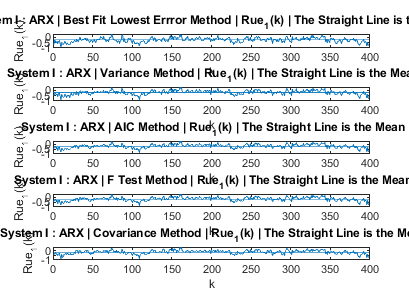


%%

figure()  % figure(6)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Rue_1(2:end), 1:N_val-1, mean(BestFit_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | Best Fit Lowest Errror Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Rue_1(2:end), 1:N_val-1, mean(Var_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | Variance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Rue_1(2:end), 1:N_val-1, mean(AIC_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | AIC Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Rue_1(2:end), 1:N_val-1, mean(FTest_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | F Test Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")


subplot(5,1,5)
plot(1:N_val-1,Cov_Rue_1(2:end), 1:N_val-1, mean(Cov_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : ARX | Covariance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

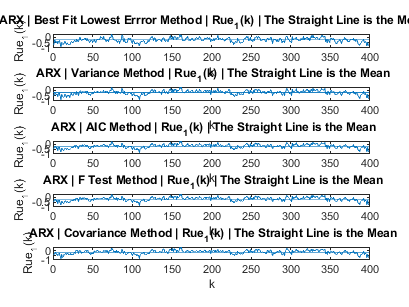



%%

figure()  % figure(6)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Rue_1(2:end), 1:N_val-1, mean(BestFit_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | Best Fit Lowest Errror Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Rue_1(2:end), 1:N_val-1, mean(Var_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | Variance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Rue_1(2:end), 1:N_val-1, mean(AIC_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | AIC Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Rue_1(2:end), 1:N_val-1, mean(FTest_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | F Test Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")


subplot(5,1,5)
plot(1:N_val-1,Cov_Rue_1(2:end), 1:N_val-1, mean(Cov_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | Covariance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")



% ************************************************************************

fprintf("*****************************************************************\n")

*****************************************************************


fprintf("*****************************************************************\n")

*****************************************************************


#### System II

%%

% System Z2 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System II Identification Begins:------------------------------\n")

>>> System II Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u2)*Ts-Ts;
t_val = 0:Ts:length(u2_val)*Ts-Ts;
N = length(y2);
N_val = length(y2_val);

%%

fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    U = arx_U_builder_3(u2, y2, na, nb, nk);
    theta_hat_2 = inv(U'*U)*U'*y2;
    y_hat_2 = form_tf_lsim_2(theta_hat_2, u2, t, na, Ts);

    [r2_arx, mse_arx] = rSQR(y2, y_hat_2);

    error = y2 - y_hat_2;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    covariance = variance*inv(U'*U);
    cov = trace(covariance)/p;
    covs = [covs; cov];

    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_arx, mse_arx, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_arx];
    MSEs = [MSEs; mse_arx];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.031862 | MSE=72.612186 | var=72.855036 | s_hat=43567.311417 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.486066 | MSE=38.546050 | var=38.804748 | s_hat=23127.629821 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.579322 | MSE=31.551626 | var=31.870329 | s_hat=18930.975512 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.613721 | MSE=28.971637 | var=29.363145 | s_hat=17382.982122 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.623674 | MSE=28.225164 | var=28.703556 | s_hat=16935.098221 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.634707 | MSE=27.397693 | var=27.956829 | s_hat=16438.615740 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.639819 | MSE=27.014286 | var=27.659678 | s_hat=16208.571595 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.644257 | MSE=26.681402 | var=27.412400 | s_hat=16008.841380 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.650711 | MSE=26.197365 | var=27.007593 | s_hat=15718.419203 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.654653 | MSE=25.901662 | var=26.794823 | s_hat=15540.997257 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.662428 | MSE=25.318571 | var=26.282253 | s_hat=15191.142470 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.664225 | MSE=25.183790 | var=26.233114 | s_hat=15110.273846 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.665462 | MSE=25.091014 | var=26.227541 | s_hat=15054.608645 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.665907 | MSE=25.057612 | var=26.284208 | s_hat=15034.567163 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.666068 | MSE=25.045524 | var=26.363710 | s_hat=15027.314630 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.668452 | MSE=24.866728 | var=26.267671 | s_hat=14920.036971 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.674250 | MSE=24.431846 | var=25.899484 | s_hat=14659.107755 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.675612 | MSE=24.329697 | var=25.882657 | s_hat=14597.818318 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.674158 | MSE=24.438787 | var=26.091232 | s_hat=14663.272206 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.675610 | MSE=24.329867 | var=26.067715 | s_hat=14597.920212 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.675988 | MSE=24.301531 | var=26.130679 | s_hat=14580.918839 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.677439 | MSE=24.192685 | var=26.107214 | s_hat=14515.611146 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.678675 | MSE=24.100015 | var=26.101099 | s_hat=14460.009092 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.680043 | MSE=23.997349 | var=26.084075 | s_hat=14398.409297 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.680383 | MSE=23.971879 | var=26.151140 | s_hat=14383.127152 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.684519 | MSE=23.661698 | var=25.906968 | s_hat=14197.018608 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.685284 | MSE=23.604289 | var=25.938780 | s_hat=14162.573649 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.686112 | MSE=23.542226 | var=25.965691 | s_hat=14125.335663 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.687051 | MSE=23.471773 | var=25.983512 | s_hat=14083.063565 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.690508 | MSE=23.212459 | var=25.791621 | s_hat=13927.475412 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.691122 | MSE=23.166471 | var=25.836213 | s_hat=13899.882653 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.690935 | MSE=23.180452 | var=25.948267 | s_hat=13908.270982 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.691337 | MSE=23.150295 | var=26.011568 | s_hat=13890.177173 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.691815 | MSE=23.114473 | var=26.068954 | s_hat=13868.683516 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.691992 | MSE=23.101187 | var=26.152288 | s_hat=13860.712449 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.692444 | MSE=23.067314 | var=26.212857 | s_hat=13840.388236 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.692441 | MSE=23.067490 | var=26.312726 | s_hat=13840.493848 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.693857 | MSE=22.961302 | var=26.291567 | s_hat=13776.781072 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.693808 | MSE=22.964975 | var=26.396523 | s_hat=13778.985013 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.694182 | MSE=22.936957 | var=26.465719 | s_hat=13762.173927 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.694530 | MSE=22.910854 | var=26.537669 | s_hat=13746.512384 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.694604 | MSE=22.905312 | var=26.634083 | s_hat=13743.186985 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.694544 | MSE=22.909763 | var=26.742914 | s_hat=13745.857563 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.696221 | MSE=22.784006 | var=26.700007 | s_hat=13670.403362 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.696207 | MSE=22.785044 | var=26.805934 | s_hat=13671.026136 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.697497 | MSE=22.688290 | var=26.797193 | s_hat=13612.973795 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.698469 | MSE=22.615384 | var=26.816661 | s_hat=13569.230650 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.699775 | MSE=22.517472 | var=26.806515 | s_hat=13510.483343 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.699792 | MSE=22.516203 | var=26.911796 | s_hat=13509.721520 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.700740 | MSE=22.445086 | var=26.934103 | s_hat=13467.051543 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.701477 | MSE=22.389789 | var=26.975649 | s_hat=13433.873334 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.701618 | MSE=22.379195 | var=27.071607 | s_hat=13427.517202 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.702000 | MSE=22.350543 | var=27.146409 | s_hat=13410.325844 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.702653 | MSE=22.301569 | var=27.197035 | s_hat=13380.941406 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.704029 | MSE=22.198400 | var=27.181714 | s_hat=13319.039782 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.705521 | MSE=22.086467 | var=27.155492 | s_hat=13251.880246 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.705108 | MSE=22.117470 | var=27.305518 | s_hat=13270.481872 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.705501 | MSE=22.087981 | var=27.381795 | s_hat=13252.788845 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.706821 | MSE=21.989007 | var=27.372208 | s_hat=13193.404160 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.707415 | MSE=21.944414 | var=27.430517 | s_hat=13166.648385 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.709602 | MSE=21.780402 | var=27.339417 | s_hat=13068.241137 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.709419 | MSE=21.794161 | var=27.471631 | s_hat=13076.496559 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.709619 | MSE=21.779101 | var=27.568482 | s_hat=13067.460302 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.710135 | MSE=21.740422 | var=27.636130 | s_hat=13044.253318 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.710396 | MSE=21.720881 | var=27.728784 | s_hat=13032.528564 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.710459 | MSE=21.716132 | var=27.841194 | s_hat=13029.678903 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.710231 | MSE=21.733222 | var=27.982689 | s_hat=13039.933161 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.710656 | MSE=21.701322 | var=28.062054 | s_hat=13020.793027 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.710657 | MSE=21.701256 | var=28.183449 | s_hat=13020.753357 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.713086 | MSE=21.519116 | var=28.068412 | s_hat=12911.469629 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.714607 | MSE=21.405019 | var=28.041510 | s_hat=12843.011366 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.715004 | MSE=21.375209 | var=28.125275 | s_hat=12825.125336 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=0.715067 | MSE=21.370529 | var=28.242989 | s_hat=12822.317206 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.717426 | MSE=21.193602 | var=28.133100 | s_hat=12716.161141 | 


-------------------------------------------------------------


>>> Degree = 75 : R2=0.716840 | MSE=21.237560 | var=28.316747 | s_hat=12742.535974 | 


-------------------------------------------------------------


>>> Degree = 76 : R2=0.716840 | MSE=21.237522 | var=28.443110 | s_hat=12742.513075 | 


-------------------------------------------------------------


>>> Degree = 77 : R2=0.719169 | MSE=21.062842 | var=28.335661 | s_hat=12637.704936 | 


-------------------------------------------------------------


>>> Degree = 78 : R2=0.719458 | MSE=21.041162 | var=28.434003 | s_hat=12624.697135 | 


-------------------------------------------------------------


>>> Degree = 79 : R2=0.720179 | MSE=20.987097 | var=28.489272 | s_hat=12592.258215 | 


-------------------------------------------------------------


>>> Degree = 80 : R2=0.720880 | MSE=20.934568 | var=28.547138 | s_hat=12560.740504 | 


-------------------------------------------------------------


>>> Degree = 81 : R2=0.720941 | MSE=20.929963 | var=28.671182 | s_hat=12557.977639 | 


-------------------------------------------------------------


>>> Degree = 82 : R2=0.725805 | MSE=20.565154 | var=28.300671 | s_hat=12339.092474 | 


-------------------------------------------------------------


>>> Degree = 83 : R2=0.728613 | MSE=20.354521 | var=28.139891 | s_hat=12212.712824 | 


-------------------------------------------------------------


>>> Degree = 84 : R2=0.728774 | MSE=20.342439 | var=28.253388 | s_hat=12205.463582 | 


-------------------------------------------------------------


>>> Degree = 85 : R2=0.729040 | MSE=20.322486 | var=28.356958 | s_hat=12193.491752 | 


-------------------------------------------------------------


>>> Degree = 86 : R2=0.729453 | MSE=20.291557 | var=28.446107 | s_hat=12174.933919 | 


-------------------------------------------------------------


>>> Degree = 87 : R2=0.729284 | MSE=20.304184 | var=28.597442 | s_hat=12182.510409 | 


-------------------------------------------------------------


>>> Degree = 88 : R2=0.729488 | MSE=20.288953 | var=28.710782 | s_hat=12173.371758 | 


-------------------------------------------------------------


>>> Degree = 89 : R2=0.729629 | MSE=20.278330 | var=28.831748 | s_hat=12166.997717 | 


-------------------------------------------------------------


>>> Degree = 90 : R2=0.729952 | MSE=20.254131 | var=28.934473 | s_hat=12152.478773 | 


-------------------------------------------------------------


>>> Degree = 91 : R2=0.730417 | MSE=20.219221 | var=29.022806 | s_hat=12131.532831 | 


-------------------------------------------------------------


>>> Degree = 92 : R2=0.733067 | MSE=20.020507 | var=28.875732 | s_hat=12012.304430 | 


-------------------------------------------------------------


>>> Degree = 93 : R2=0.733380 | MSE=19.996988 | var=28.981142 | s_hat=11998.192835 | 


-------------------------------------------------------------


>>> Degree = 94 : R2=0.734759 | MSE=19.893584 | var=28.971239 | s_hat=11936.150618 | 


-------------------------------------------------------------


>>> Degree = 95 : R2=0.734243 | MSE=19.932293 | var=29.169209 | s_hat=11959.375709 | 


-------------------------------------------------------------


>>> Degree = 96 : R2=0.734607 | MSE=19.904999 | var=29.272057 | s_hat=11942.999139 | 


-------------------------------------------------------------


>>> Degree = 97 : R2=0.735571 | MSE=19.832695 | var=29.309401 | s_hat=11899.616916 | 


-------------------------------------------------------------


>>> Degree = 98 : R2=0.737037 | MSE=19.722699 | var=29.291137 | s_hat=11833.619223 | 


-------------------------------------------------------------


>>> Degree = 99 : R2=0.737140 | MSE=19.715029 | var=29.425416 | s_hat=11829.017119 | 


-------------------------------------------------------------


>>> Degree = 100 : R2=0.737560 | MSE=19.683485 | var=29.525227 | s_hat=11810.090703 | 


-------------------------------------------------------------



fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 100 


na = bestFitDegree;
nb = bestFitDegree;
p = na+nb;

BestFitU = arx_U_builder_3(u2, y2, na, nb, nk);
BestFitModel_2 = inv(BestFitU'*BestFitU)*BestFitU'*y2;
BestFit_y_hat_2 = form_tf_lsim_2(BestFitModel_2, u2_val, t_val, na, Ts);

G =
 
                                                                                                         
   -6.771 z^-1 - 0.1819 z^-2 + 1.514 z^-3 + 16.19 z^-4 + 10.97 z^-5 - 36.61 z^-6 + 33.01 z^-7            
                                                                                                         
           + 13.78 z^-8 - 19.45 z^-9 + 5.383 z^-10 + 13.39 z^-11 - 0.4511 z^-12 + 17 z^-13 + 24.03 z^-14 
                                                                                                         
           - 9.561 z^-15 + 1.32 z^-16 + 43.49 z^-17 + 11.77 z^-18 - 18.25 z^-19 + 43.74 z^-20            
                                                                                                         
           + 13.16 z^-21 + 7.488 z^-22 + 28.82 z^-23 - 4.357 z^-24 - 15.58 z^-25 + 53.59 z^-26           
                                                                                                         
           - 6.113 z^-27 + 8.534 z^-28 -


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 30 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 30 


na = minVarIndex;
nb = minVarIndex;
p = na+nb;

VarU = arx_U_builder_3(u2, y2, na, nb, nk);
VarModel_2 = inv(VarU'*VarU)*VarU'*y2;
Var_y_hat_2 = form_tf_lsim_2(VarModel_2, u2_val, t_val, na, Ts);

G =
 
                                                                                                       
    -2.579 z^-1 - 0.8101 z^-2 + 0.05998 z^-3 + 18.08 z^-4 + 9.197 z^-5 - 34.25 z^-6 + 35.18 z^-7       
                                                                                                       
            + 14.24 z^-8 - 17.89 z^-9 + 3.292 z^-10 + 16.56 z^-11 + 0.2597 z^-12 + 16.46 z^-13         
                                                                                                       
            + 27.42 z^-14 - 8.051 z^-15 + 2.633 z^-16 + 47.1 z^-17 + 13.38 z^-18 - 17.45 z^-19         
                                                                                                       
            + 44.26 z^-20 + 15.47 z^-21 + 10.42 z^-22 + 30.55 z^-23 + 1.885 z^-24 - 11.82 z^-25        
                                                                                                       
                                  + 59.02 z^-26 - 0.8562 z


fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | CoVariance Method=================\n")

===============Degree Extraction | CoVariance Method=================



maxCovIndex = find(covs == min(covs));
fprintf(">>> Since the minimum CovMatrix trace occurs in iteration %d ;\n", maxCovIndex)

>>> Since the minimum CovMatrix trace occurs in iteration 1 ;


fprintf("    Degree = %d \n", maxCovIndex)

    Degree = 1 


na = maxCovIndex;
nb = maxCovIndex;
p = na+nb;

CovU_2 = arx_U_builder_3(u2,y2,na,nb,1);
CovModel_2 = inv(CovU_2'*CovU_2)*CovU_2'*y2;
Cov_y_hat_2 = form_tf_lsim_2(CovModel_2, u2_val, t_val, na, Ts);

G =
 
    1.884 z^-1
  ---------------
  1 - 0.6361 z^-1
 
Sample time: 0.5 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 17 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 17 



na = minAICIndex;
nb = minAICIndex;
p = na+nb;

AICU_2 = arx_U_builder_3(u2, y2, na, nb, nk);
AICModel_2 = inv(AICU_2'*AICU_2)*AICU_2'*y2;
AIC_y_hat_2 = form_tf_lsim_2(AICModel_2, u2_val, t_val, na, Ts);

G =
 
                                                                                                       
    -14.78 z^-1 + 3.619 z^-2 + 0.5736 z^-3 + 15.79 z^-4 + 4.257 z^-5 - 41.52 z^-6 + 29.68 z^-7         
                                                                                                       
            + 6.409 z^-8 - 22.24 z^-9 + 1.371 z^-10 + 14.21 z^-11 - 3.426 z^-12 + 10.42 z^-13          
                                                                                                       
                                                 + 18.32 z^-14 - 21.49 z^-15 - 15.7 z^-16 + 45.14 z^-17
                                                                                                       
  -------------------------------------------------------------------------------------------------------
                                                                                                         
  1 - 0.06877 z^-1 - 0.04002 z^-2 - 0.01462 z^-3 + 0.0


fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.21 as


fprintf("    Degree = %d \n", winner)

    Degree = 11 



na = winner;
nb = winner;
p = na+nb;

FTestU_2 = arx_U_builder_3(u2, y2, na, nb, nk);
FTestModel_2 = inv(FTestU_2'*FTestU_2)*FTestU_2'*y2;
FTest_y_hat_2 = form_tf_lsim_2(FTestModel_2, u2_val, t_val, na, Ts);

G =
 
                                                                                                     
  -9.183 z^-1 + 6.441 z^-2 + 1.047 z^-3 + 14.29 z^-4 + 0.8618 z^-5 - 45.18 z^-6 + 28.77 z^-7         
                                                                                                     
                                                + 7.506 z^-8 - 16.75 z^-9 + 12.11 z^-10 - 21.54 z^-11
                                                                                                     
  ---------------------------------------------------------------------------------------------------
                                                                                                     
  1 - 0.0947 z^-1 - 0.04546 z^-2 - 0.0163 z^-3 + 0.05989 z^-4 - 0.02999 z^-5 + 0.08976 z^-6          
                                                                                                     
                        + 0.01901 z^-7 + 0.04593 z^-8 + 0.003442 z^-9 - 0.00


fprintf("=================================================================\n")


%%

[BestFit_r2, BestFit_mse] = rSQR(y2_val, BestFit_y_hat_2);
[Var_r2, Var_mse] = rSQR(y2_val, Var_y_hat_2);
[AIC_r2, AIC_mse] = rSQR(y2_val, AIC_y_hat_2);
[Cov_r2, Cov_mse] = rSQR(y2_val, Cov_y_hat_2);
[FTest_r2, FTest_mse] = rSQR(y2_val, FTest_y_hat_2);


fprintf("===========================System III===========================\n")

===========================System III===========================


fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", BestFit_r2, BestFit_mse)

    R2 value : 0.4403   | MSE : 49.4593 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Var_r2, Var_mse)

    R2 value : 0.6080   | MSE : 34.6387 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Covariance Method:\n")

>>> Covariance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Cov_r2, Cov_mse)

    R2 value : 0.0418   | MSE : 84.6691 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", AIC_r2, AIC_mse)

    R2 value : 0.6918   | MSE : 27.2343 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", FTest_r2, FTest_mse)

    R2 value : 0.6918   | MSE : 27.2300 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

BestFitError_2 = y2_val - BestFit_y_hat_2;
VarError_2 = y2_val - Var_y_hat_2;
CovError_2 = y2_val - Cov_y_hat_2;
AICError_2 = y2_val - AIC_y_hat_2;
FTestError_2 = y2_val - FTest_y_hat_2;

for k=0:N_val-1
    BestFit_Ree_2(k+1,1) = AutoCorrelate(BestFitError_2, k);
    Var_Ree_2(k+1,1) = AutoCorrelate(VarError_2, k);
    Cov_Ree_2(k+1,1) = AutoCorrelate(CovError_2, k);
    AIC_Ree_2(k+1,1) = AutoCorrelate(AICError_2, k);
    FTest_Ree_2(k+1,1) = AutoCorrelate(FTestError_2, k);
end

for k=0:N_val-1
    BestFit_Rue_2(k+1,1) = CrossCorrelate(u2_val, BestFitError_2, k);
    Var_Rue_2(k+1,1) = CrossCorrelate(u2_val, VarError_2, k);
    Cov_Rue_2(k+1,1) = CrossCorrelate(u2_val, CovError_2, k);
    AIC_Rue_2(k+1,1) = CrossCorrelate(u2_val, AICError_2, k);
    FTest_Rue_2(k+1,1) = CrossCorrelate(u2_val, FTestError_2, k);
end


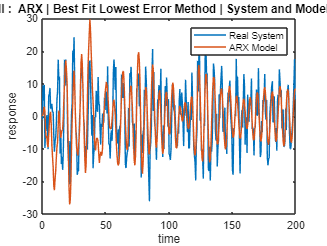


%%
figure()  % figure(1)
plot(t_val,y2_val,t_val,BestFit_y_hat_2)
legend('Real System','ARX Model')
title(" System II :  ARX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

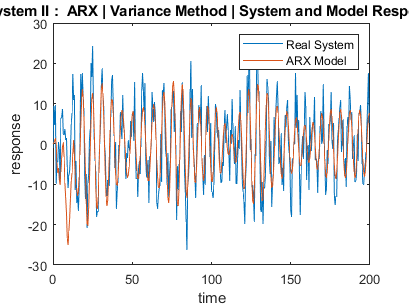


figure()  % figure(2)
plot(t_val,y2_val,t_val,Var_y_hat_2)
legend('Real System','ARX Model')
title(" System II :  ARX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

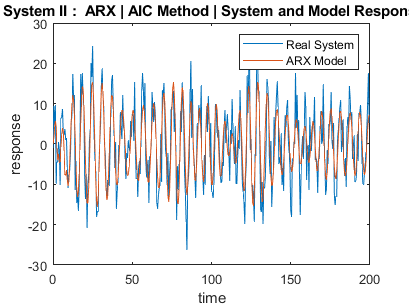


figure()  % figure(3)
plot(t_val,y2_val,t_val,AIC_y_hat_2)
legend('Real System','ARX Model')
title(" System II :  ARX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

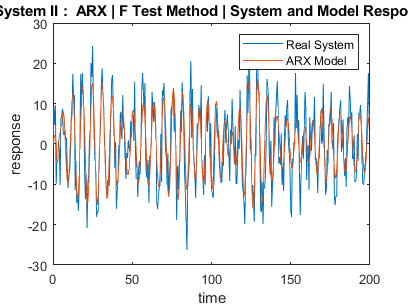


figure()  % figure(4)
plot(t_val,y2_val,t_val,FTest_y_hat_2)
legend('Real System','ARX Model')
title(" System II :  ARX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

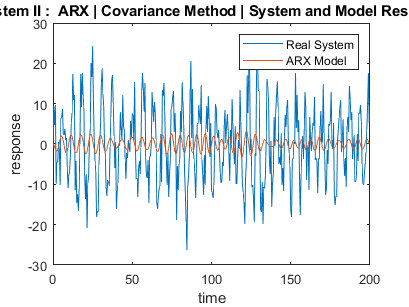


figure()  % figure(7)
plot(t_val,y2_val,t_val,Cov_y_hat_2)
legend('Real System','ARX Model')
title(" System II :  ARX | Covariance Method | System and Model Response")
xlabel("time")
ylabel("response")


%%

figure()  % figure(5)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Ree_2(2:end), 1:N_val-1, mean(BestFit_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | Best Fit Lowest Errror Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Ree_2(2:end), 1:N_val-1, mean(Var_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | Variance Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Ree_2(2:end), 1:N_val-1, mean(AIC_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | AIC Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Ree_2(2:end), 1:N_val-1, mean(FTest_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | F Test Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,5)
plot(1:N_val-1,Cov_Ree_2(2:end), 1:N_val-1, mean(Cov_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | Covariance Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")


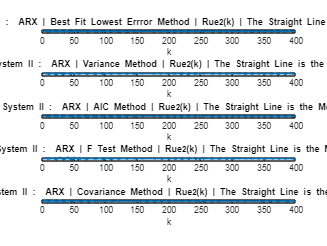


%%

figure()  % figure(6)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Rue_2(2:end), 1:N_val-1, mean(BestFit_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | Best Fit Lowest Errror Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Rue_2(2:end), 1:N_val-1, mean(Var_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | Variance Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Rue_2(2:end), 1:N_val-1, mean(AIC_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | AIC Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Rue_2(2:end), 1:N_val-1, mean(FTest_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | F Test Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")


subplot(5,1,5)
plot(1:N_val-1,Cov_Rue_2(2:end), 1:N_val-1, mean(Cov_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II :  ARX | Covariance Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")



fprintf("*****************************************************************\n")

*****************************************************************


fprintf("*****************************************************************\n")

*****************************************************************
